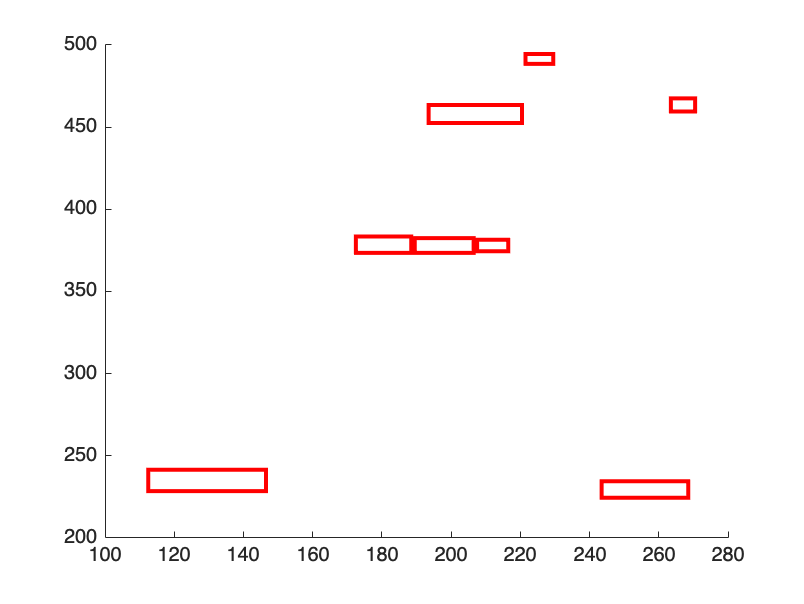

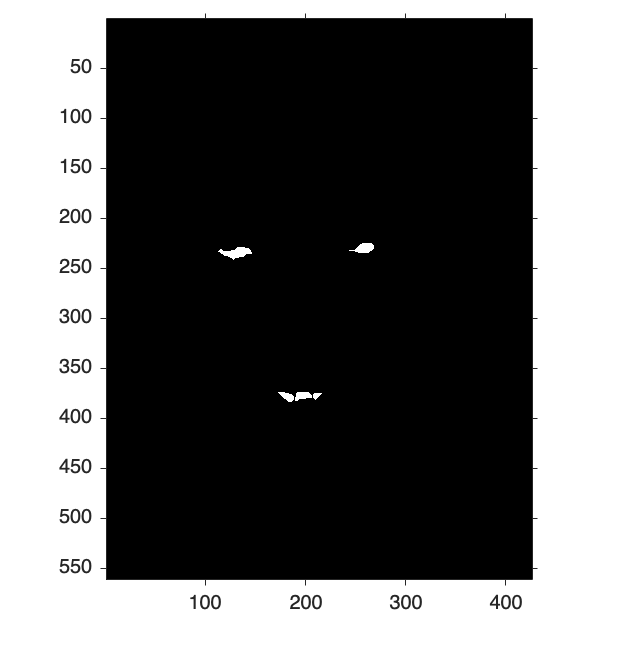

mouth_centers =    66.9032  279.9516
  181.6390  273.1865
  197.4474  379.7225
  158.9939  299.6455
  264.1849  285.7984


mouth_orientations =   -66.6497
    8.0114
    1.3507
  -66.6257
  -29.8141


x_lengths =    17.6355
   98.9229
  100.8774
   25.0617
   87.7730


y_lengths =    14.0117
   75.4876
   58.3190
   17.8617
   41.9180


tempeyes =   130.9697  234.2165
  211.1053  377.1316


dist_em_1 =   159.9728
         0
         0
         0
         0


dist_em_2 =    13.9015
         0
         0
         0
         0


tempeyes =   130.9697  234.2165
  258.9295  229.7244


dist_em_1 =   159.9728
  159.9728
         0
         0
         0


dist_em_2 =    13.9015
  162.1095
         0
         0
         0


tempeyes =   181.7391  378.0543
  211.1053  377.1316


dist_em_1 =   159.9728
  159.9728
   15.7966
         0
         0


dist_em_2 =    13.9015
  162.1095
   13.9015
         0
         0


tempeyes =   181.7391  378.0543
  258.9295  229.7244


dist_em_1 =   159.9728
  159.9728
   15.7966
   15.7966
         0


dist_em_2 =    13.9015
  162.1095
   13.9015
  162.1095
         0


tempeyes =   197.2870  377.3241
  211.1053  377.1316


dist_em_1 =   159.9728
  159.9728
   15.7966
   15.7966
    2.4038


dist_em_2 =    13.9015
  162.1095
   13.9015
  162.1095
   13.9015


tempeyes =   197.2870  377.3241
  258.9295  229.7244


dist_em_1 =   159.9728
  159.9728
   15.7966
   15.7966
    2.4038
    2.4038


dist_em_2 =    13.9015
  162.1095
   13.9015
  162.1095
   13.9015
  162.1095


dist_em_1 =   159.9728
  159.9728
   15.7966
   15.7966
    2.4038
    2.4038


dist_em_2 =    13.9015
  162.1095
   13.9015
  162.1095
   13.9015
  162.1095


index = 6

Dist1: 159.9728 Dist2: 13.9015
Dist between em1 em2: 146.0714
Dist_eyes 163.8488
Dist1: 159.9728 Dist2: 162.1095
Dist between em1 em2: 2.1367
Dist_eyes 163.8488
Dist1: 159.9728 Dist2: 13.9015
Dist between em1 em2: 146.0714
Dist_eyes 163.8488
Dist1: 159.9728 Dist2: 162.1095
Dist between em1 em2: 2.1367
Dist_eyes 163.8488
Dist1: 159.9728 Dist2: 13.9015
Dist between em1 em2: 146.0714
Dist_eyes 163.8488
Dist1: 159.9728 Dist2: 162.1095
Dist between em1 em2: 2.1367
Dist_eyes 163.8488
Dist1: 159.9728 Dist2: 162.1095
Dist between em1 em2: 2.1367
Dist_eyes 128.0386
Dist diff: 2.1367
Dist1: 159.9728 Dist2: 13.9015
Dist between em1 em2: 146.0714
Dist_eyes 128.0386
Dist1: 159.9728 Dist2: 162.1095
Dist between em1 em2: 2.1367
Dist_eyes 128.0386
Dist1: 159.9728 Dist2: 13.9015
Dist between em1 em2: 146.0714
Dist_eyes 128.0386
Dist1: 159.9728 Dist2: 162.1095
Dist between em1 em2: 2.1367
Dist_eyes 128.0386
Dist1: 15.7966 Dist2: 13.9015
Dist between em1 em2: 1.8951
Dist_eyes 29.3806
Dist1: 15.7966 Dist2

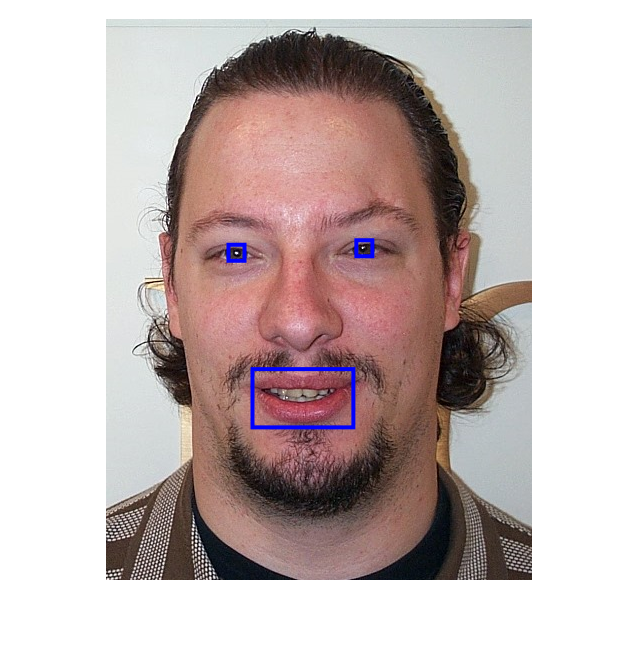

clear;

image = imread("images/DB1/db1_05.jpg");
% img_gray = gray_world(image);
% img_white = white_patch(image);
% img_mask = face_mask(image);

% eigen = eigenface(image);
% imshow(eigen);

%--------Test normalization---------
% eye coordinates
eyePosition = detect_face(image);


%imshow(image); %Original image

eyeL = eyePosition(1,:);
eyeR = eyePosition(2,:);

%Eigenface
norm = normalization_face(eyeL, eyeR, image)

dist_eyes_x = 127.9598

ans =    561   426     3


x_center = 213

y_center = 280.5000

dist_x = 82

dist_y = 46

pos_eyeX = 130.9697

pos_eyeY = 234.2165

skalfaktor = 0.8987

norm = 301×111×3 uint8 array
norm(:,:,1) =

   131   148   164   174   172   177   186   183   184   184   186   191   190   189   187   192   193   195   193   196   194   196   198   204   201   198   199   204   206   203   199   199   210   211   220   221   215   216   217   223   230   228   221   224   236   238   232   224   219   222   230   235   226   219   226   229   230   233   227   218   224   226   217   220   221   221   216   220   226   220   224   227   222   220   220   221   224   221   219   215   210   212   218   217   214   223   223   227   224   215   211   217   222   221   224   221   220   218   219   214   215   218   224   224   214   218   221   218   217   216   212
   134   156   167   175   173   182   191   183   179   182   192   195   193   189   184   192   196   193   195   204   199   198   202   209   204   201   196   202   204   203   196   203   212   214   216   217   216   218   220   219   217   225   217   221   230   231   228   231 

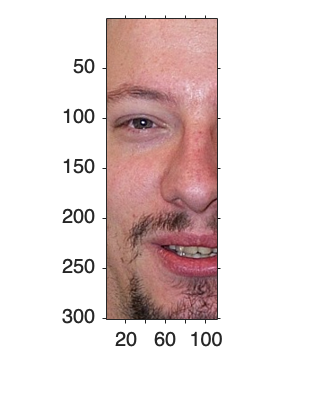


axis on


%-------normalization--------------


% scale
% avståndet mellan ögonen ska vara samma för alla bilder. hitta
% skalningsfaktor(kvoten) det vi har delat på det vi vill ha ger
% skalningsfaktorn, klör imresize med skaliningsfaktorn
%sedan kan vi croppa, 50 uppåt, 50 åt sidorna, 100 nedåt

